Frame dragging with Voronoi cells

- Create mesh.

- Import mesh points.

- Draw Voronoi cells.

- Define center.

- Rotate around center with steps over time.

- Redraw Voronoi cells at every step.

- Calculate bending of the lines.

- Look for limit.

- Do the same dilated and compressed space.

t = pi/12:pi/12:2*pi;
% pgon = polyshape({[-0.5 -0.5 0.5 0.5], 0.25*cos(t)}, ...
%                  {[0.5 -0.5 -0.5 0.5], 0.25*sin(t)})
% pgon = polyshape({[-0.5 -0.5 0.5 0.5]}, ...
%                  {[0.5 -0.5 -0.5 0.5]})
pgon = polyshape({0.25*cos(t)}, ...
                 {0.25*sin(t)})

pgon =   polyshape with properties:

      Vertices: [24×2 double]
    NumRegions: 1
      NumHoles: 0


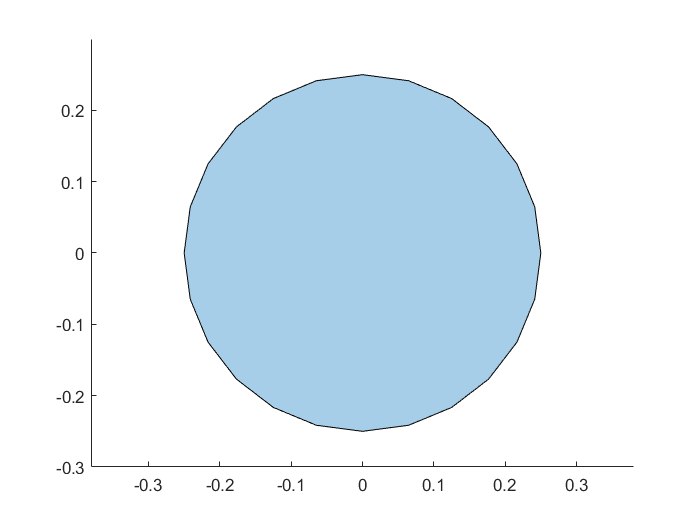

plot(pgon)
axis equal

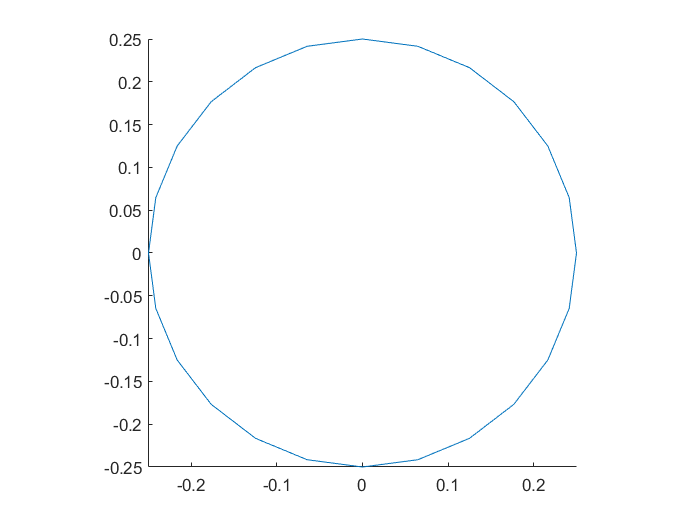


tr = triangulation(pgon);
model = createpde;

tnodes = tr.Points';
telements = tr.ConnectivityList';

geometryFromMesh(model,tnodes,telements);
pdegplot(model)

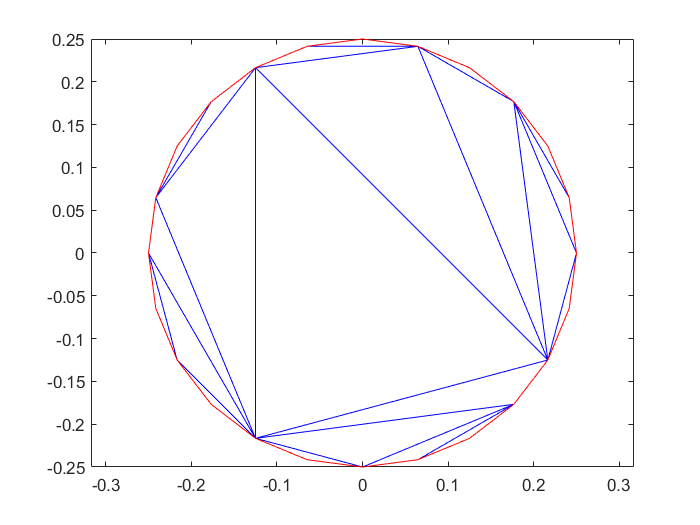


figure
pdemesh(model)